## User Input

f0 = 264e3;             % DRSSTC resonant frequency, Hz
Vbus = 340;             % DRSSTC bus voltage, V
I_ocd_lim = 300;        % OCD current limit, A    
N = 1;                  % number of cycles to plot
phi = 0;                % Phase of inverter switching waveform w.r.t primary current, rad

## Compute

t0 = 1/f0;              % DRSSTC resonant period, sec
w0 = 2*pi*f0;           % angular resonant freq, rad/s

% sampling freq, Hz (over-sample to see higher-order harmonics)
fs = f0*10000;
% sim time step, sec
ts = 1/fs;              
t=0:ts:N*t0;            % time-series

V_1pk = (4/pi)*Vbus;    % Peak amplitude of fundamental, V
y_1 = V_1pk*gen_square_wave(t, w0, 1);      % Generate "square" wave with only fundamental
y_9 = V_1pk*gen_square_wave(t, w0, 9);      % Generate "square" wave with odd harmonics 1-9
y_99 = V_1pk*gen_square_wave(t, w0, 99);    % Generate "square" wave with odd harmonics 1-99



## Plot

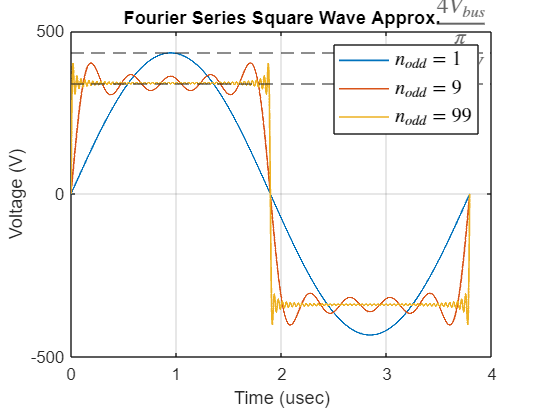

t_usec = t*1e6;

line_width = 1;

figure();
plot(t_usec,y_1,"LineWidth",line_width);
hold on;
plot(t_usec,y_9,"LineWidth",line_width);
hold on;
plot(t_usec,y_99,"LineWidth",line_width);
grid on;
yline(V_1pk, '--', '$\frac{4V_{bus}}{\pi}$', 'Interpreter', 'latex', 'FontSize', 14);
yline(Vbus, '--', '$V_{bus}=340V$', 'Interpreter', 'latex', 'FontSize', 14);
legend("$n_{odd}=1$","$n_{odd}=9$","$n_{odd}=99$",'Interpreter', 'latex','FontSize', 12);
xlabel('Time (usec)');
ylabel('Voltage (V)');
title('Fourier Series Square Wave Approx.');